# Dimensionality Reduction

## Import Data

clear
clear all
close all
clc
format shorteng

data = import_whole('Set 1.txt');

% CLEAN DATA
% Swap Uin and Q
v = data(:, 5);
data(:, 5) = data(:, 6);
data(:, 6) = v;
clear v
% convert Tamb from kelvin to DegC
data(:, "Tamb") = data(:, "Tamb") - 273.15;
% convert from m to mm
data(:, "length") = data(:, "length") .* 1000;
data(:, "hc") = data(:, "hc") .* 1000;
data(:, "wc") = data(:, "wc") .* 1000;

% select columns 1 to 6 as features
data = data(:,1:6);

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];

## Feature Scaling

% Standardise the data
n_data = data;
n_data(:,1:6) = normalize(data(:,1:6), "zscore");

## Principal Component Analysis (PCA)

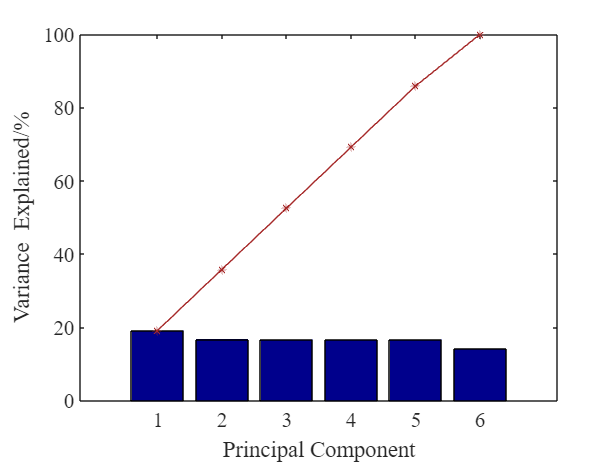

% defaults to centering data and using SVD
[coeff, transformedData, latent, tsquared, ex] = pca(n_data{:,1:6});

% Plot pareto chart
figure(1)
hold on;
bar(ex, 'FaceColor', blue)
plot(cumsum(ex),'*-','MarkerEdgeColor',red,'Color',red,'MarkerSize',6)
hold off;
% legend(["" sprintf("Cumulative explained\nvariance")],"Location","northwest");
% title("Pareto Chart of Explained Variances")
xlabel("Principal Component")
ylabel("Variance Explained/{%}")
v=get(1,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman', 'XTickLabelRotation', 0, 'XTick', 1:6);
box on

### Others

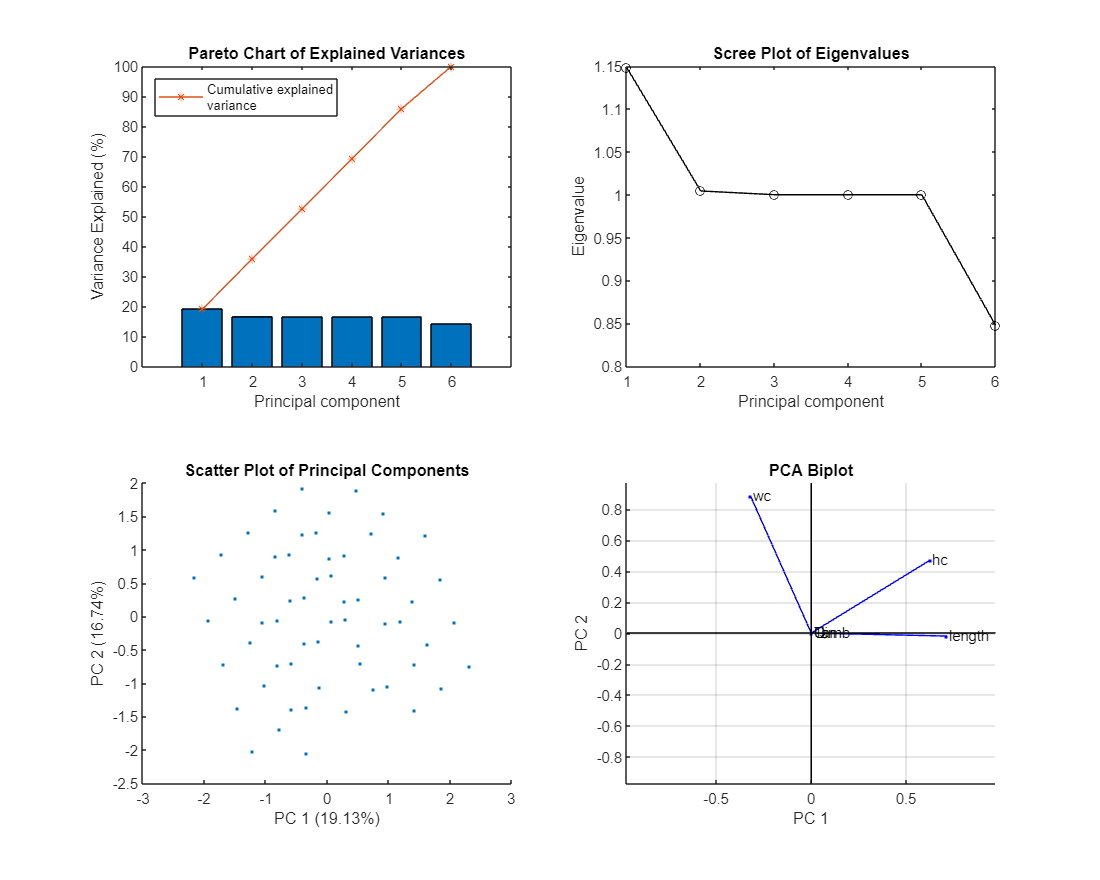

%scree plots
figure(2)
set(gcf,'Position',[0 0 1500 1200])
subplot(2,2,1)
bar(ex)
hold on;
plot(cumsum(ex),"*-");
hold off;
legend(["" sprintf("Cumulative explained\nvariance")],"Location","northwest");
title("Pareto Chart of Explained Variances")
xlabel("Principal component")
ylabel("Variance Explained (%)")

subplot(2,2,2)
plot(1:length(latent),latent,'ko-')
title('Scree Plot of Eigenvalues')
xlabel('Principal component')
ylabel('Eigenvalue')

%scatter plot
subplot(2,2,3)
scatter(transformedData(:,1),transformedData(:,2), "Marker", ".");
title("Scatter Plot of Principal Components")
xlabel('PC 1 (' + string(round(ex(1,1),2)) + '%)')
ylabel('PC 2 (' + string(round(ex(2,1),2)) + '%)')

%biplot
subplot(2,2,4)
varLabels2 = n_data(:, 1:6).Properties.VariableNames();
biplot(coeff(:,[1 2]),"VarLabels",varLabels2)
                                                                                                                                                                                                                                title("PCA Biplot")
xlabel("PC 1")
ylabel("PC 2")

% pca output
transformedData = array2table(transformedData);